# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.13 MATLAB关于画二元函数图，定义域是个封闭曲线内部，有没有大佬知道？

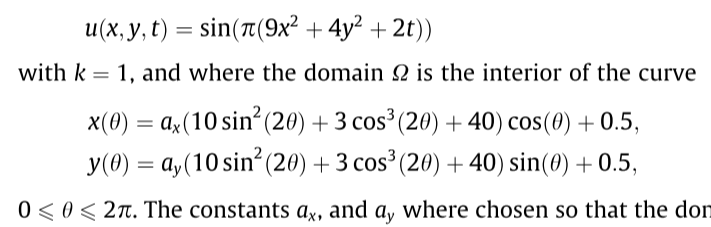

t和ax，ay都看作常数就行

原问题：[https://www.zhihu.com/question/624650797/answer/3237831544](https://www.zhihu.com/question/624650797/answer/3237831544)

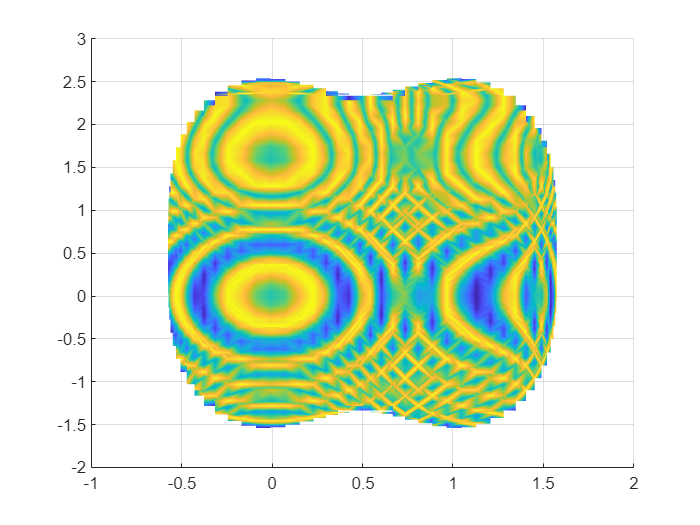

clear;clc;
theta = linspace(0, 2*pi, 100);
ax = 0.025;
ay = 0.05;
x=ax*(10.*sin(2*theta).^2+3*cos(2*theta).^3+40).*cos(theta)+0.5;
y=ay*(10.*sin(2*theta).^2+3*cos(2*theta).^3+40).*sin(theta)+0.5;
[X, Y] = meshgrid(x, y);
U = sin(pi * (9*X.^2 + 4*Y.^2 + 2));
% 设置 NaN 即不显示
in = inpolygon(X(:), Y(:), x, y);
U(~in) = NaN;
surf(X, Y, U);
shading interp
view([0, 90])